# Init add-on

addpath("ltspice2matlab/")

## Read raw

raw = LTspice2Matlab('./Universal_Biquad_tl082.raw');
t = raw.time_vect;
vin = raw.variable_mat(8,:);
vbp = raw.variable_mat(5,:);
vbs = raw.variable_mat(6,:);

## Plot

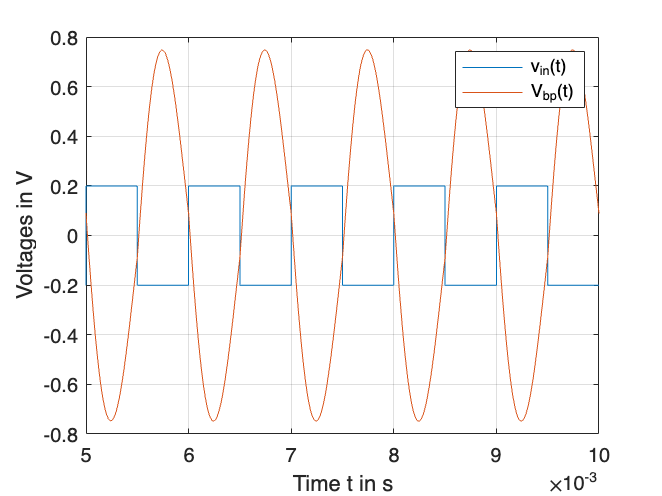

fig1 = figure(1);
plot(t, vin, t, vbp)
grid
xlabel('Time t in s')
ylabel('Voltages in V')
legend('v_{in}(t)','V_{bp}(t)')